clc
clear all

**Initializig the space and Witt Basis**


%// Imaginary unit
%i = er1*er2;
clifford_signature(4,0)
% Witt basis
f1 = 0.5*(e1+i*e3); 
f1T = 0.5*(e1-i*e3); 
f2 = 0.5*(e2+i*e4); 
f2T = 0.5*(e2-i*e4); 

Defining the states of the 2 qubit system

% Element "I"
Id = f1*f1T*f2*f2T;
% ket basis vectors multiplied by "Id" 11 
ket00 = 1*Id;
ket01 = f2T*Id;
ket10 = f1T*Id;
ket11 = f1T*f2T*Id;
bra00 = 1*Id;
bra01 = Id*f2;
bra10 = Id*f1;
bra11 = Id*f2*f1;

Gate implementations

%hadamard
h1 = (1/sqrt(2))*(f1*f1T + f1 + f1T - f1T*f1);
h2 = (1/sqrt(2))*(f2*f2T + f2 + f2T - f2T*f2);
%superposition
psi = h1*h2*ket00;

% Not operation
not1 = f1 +f1T;
not2 = f2 +f2T;
%controlled z
cz = f1*f1T + f1T*f1*f2*f2T - f1T*f1*f2T*f2;

Oracle function

%oracle
oracle1 = not2 *  cz * not2;
%reflects 10
psi2 = oracle1*psi;

Diffusion operator

%diffusion
cx = f1*f1T*f2*f2T + f1*f1T*f2T*f2 - f1T*f1*f2 - f1T*f1*f2T;
diffusion =  h1*h2*not1 * not2* cz *not2 * not1*h2*h1;
psi9 = diffusion*psi2

psi9 =    0.0000 e0  
 - 0.2500 e1   - 0.0000 e2   + ( 0.0000 + 0.2500i) e3   + ( 0.0000 + 0.0000i) e4  
 + 0.0000 e12  + ( 0.0000 - 0.0000i) e13  + ( 0.0000 - 0.0000i) e14  + ( 0.0000 + 0.0000i) e23  + ( 0.0000 - 0.0000i) e24  - 0.0000 e34 
   ( 0.0000 - 0.0000i) e123 + ( 0.0000 + 0.2500i) e124 + 0.0000 e134 - 0.2500 e234
 + 0.0000 e1234

Plotting of the results

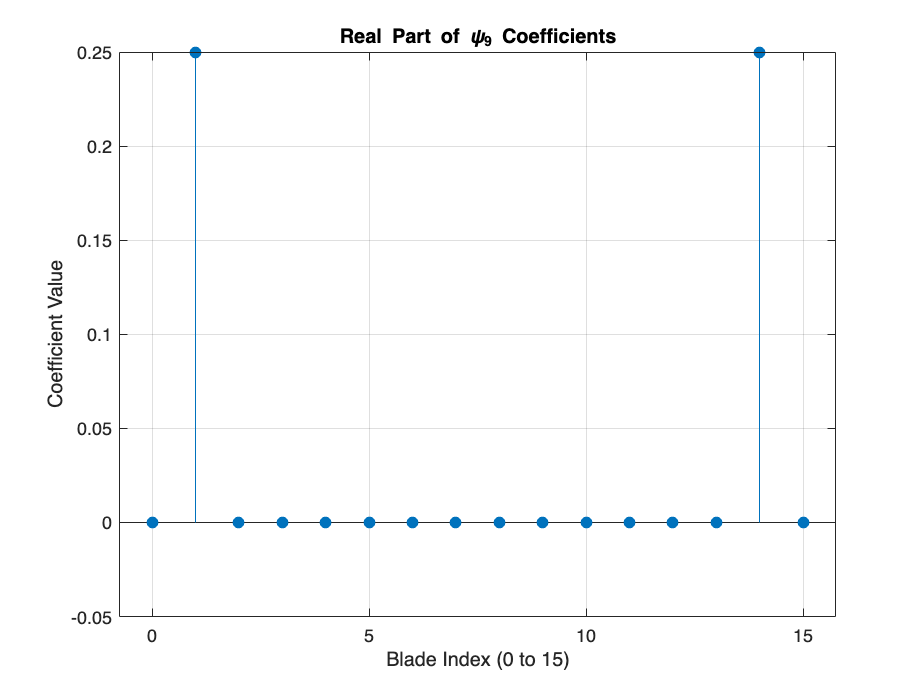

% For psi9
c_psi9 = coefficients(-psi9);
c_psi9_numeric = zeros(1, length(c_psi9)); % Preallocate
for k = 1:length(c_psi9)
    if ~isempty(c_psi9{k})
        c_psi9_numeric(k) = c_psi9{k};
    end
end

% For ket10
c_ket10 = coefficients(ket10);
c_ket10_numeric = zeros(1, length(c_ket10)); % Preallocate
for k = 1:length(c_ket10)
    if ~isempty(c_ket10{k})
        c_ket10_numeric(k) = c_ket10{k};
    end
end
% Plot psi9
figure;
stem(0:15, real(c_psi9_numeric), 'filled');
title('\psi_9 Coefficients');
xlabel('Blade Index (0 to 15)');
ylabel('Coefficient Value');
grid on;

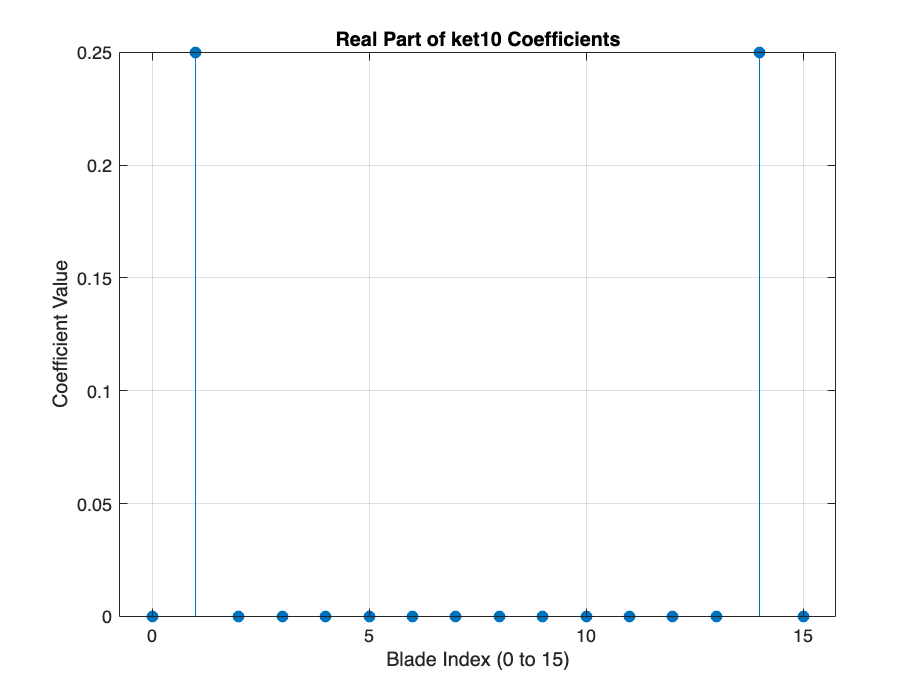


% Plot ket10
figure;
stem(0:15, real(c_ket10_numeric), 'filled');
title('ket10 Coefficients');
xlabel('Blade Index (0 to 15)');
ylabel('Coefficient Value');
grid on;